# Support Vector Classification

An example for 2D visual classification of SVM.

Written by **Junhong Zhang**, SZU, with **Matlab R2020a**

% Generate data point and initialize.
rng default;

clc;
clear;
close all;

point_num = 250;

X = 6 * rand(point_num, 2) - 3;

## Linear classification

Y1 = X(:, 1) + X(:, 2) < 0.6;
Y2 = X(:, 1) + X(:, 2) >= 1.2;

X1 = X(Y1, :);
X2 = X(Y2, :);

Y = [Y1(Y1 == 1) + 1; Y2(Y2 == 1)];
X = [X1; X2];

params.c = 1;
tic;
model = SVM_train(Y, X, params);  % or: model = SVM_train(Y, X, params, 'linear');
[~, acc] = SVM_predict(X, model, Y);
toc;

Elapsed time is 0.019794 seconds.


disp(acc);

   100



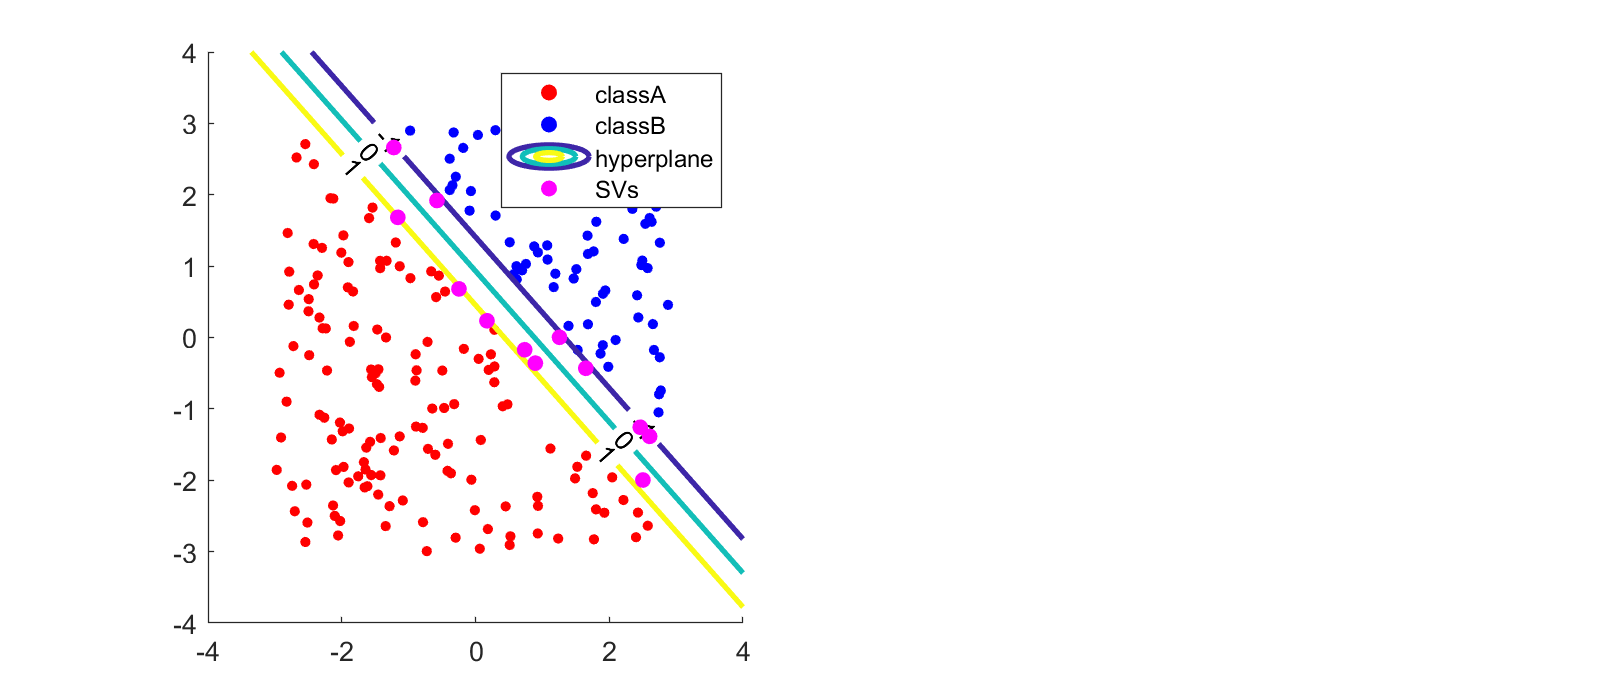

step = 100;

% Draw contour
grid_x = linspace(-4, 4, step);
grid_y = linspace(-4, 4, step);
[gridX, gridY] = meshgrid(grid_x, grid_y);
clear grid_x grid_y;

% get coordinates
XY = [gridX(:), gridY(:)];    
grid_z = SVM_predict(XY, model);
gridZ = reshape(grid_z, [step, step]);

figure('name', 'SVM demo', 'position', [300, 300, 800, 350]);
subplot(121)
hold on;
scatter(X1(:, 1), X1(:, 2), 15, 'r', 'filled');
scatter(X2(:, 1), X2(:, 2), 15, 'b', 'filled');
contour(gridX, gridY, gridZ, [0, -1, 1], 'LineWidth', 2, 'ShowText', 'on');
scatter(model.sv(:, 1), model.sv(:, 2), 35, 'm', 'filled');

legend({'classA', 'classB', 'hyperplane', 'SVs'}, 'location', 'northeast');

## Non-linear classification

Y1 = X(:, 1).^2 + X(:, 2).^2  < 4;
Y2 = X(:, 1).^2 + X(:, 2).^2 >= 5.5;

X1 = X(Y1, :);
X2 = X(Y2, :);

Y = [Y1(Y1 == 1) + 1; Y2(Y2 == 1)];
X = [X1; X2];

params.c = 3;
params.gamma = 0.04;
params.d = 2;
tic;
model = SVM_train(Y, X, params, 'poly');  % or: model = SVM_train(Y, X, params, 'linear');
[predY, acc] = SVM_predict(X, model, Y);
toc;

Elapsed time is 0.044539 seconds.


disp("Training accuracy (%):"); disp(acc);

Training accuracy (%):
   100



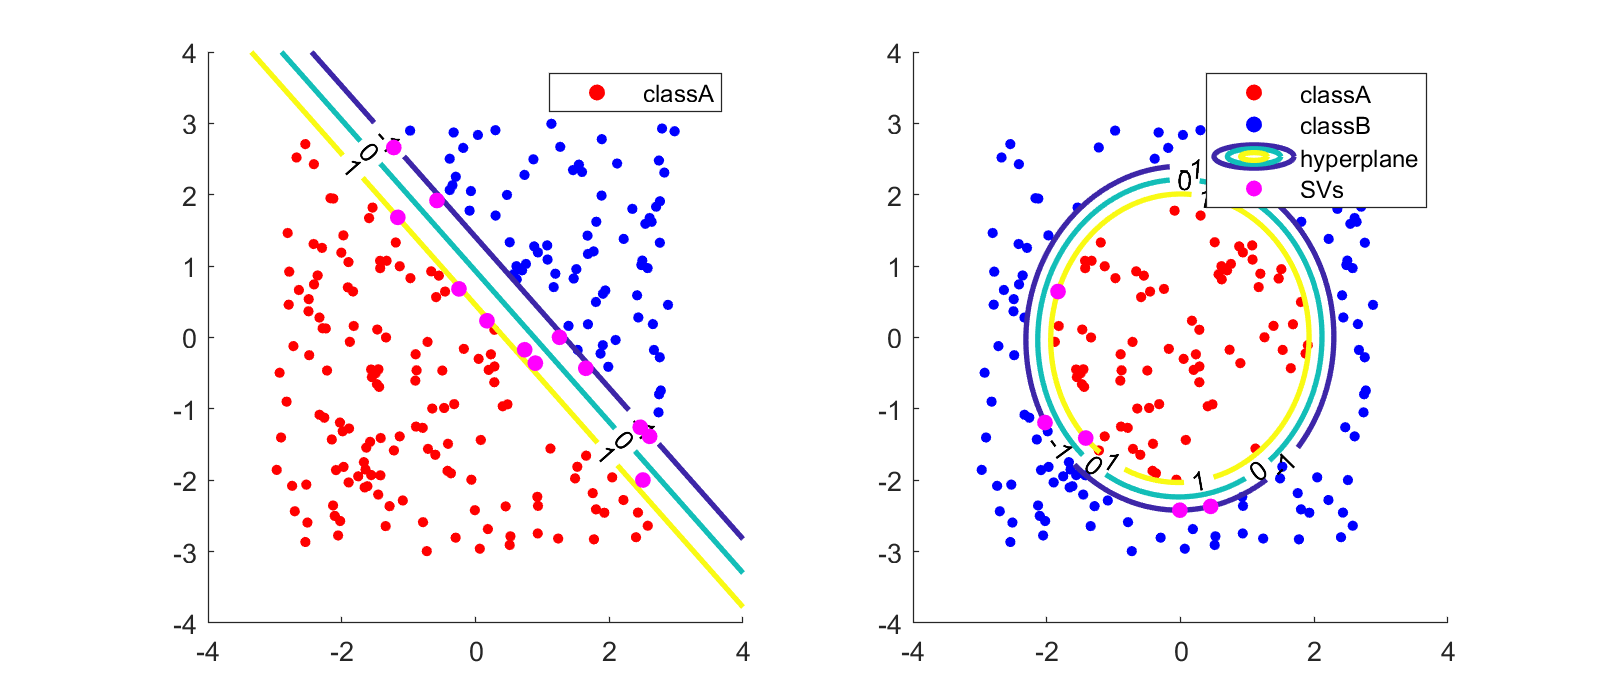


step = 100;

grid_x = linspace(-4, 4, step);
grid_y = linspace(-4, 4, step);
[gridX, gridY] = meshgrid(grid_x, grid_y);
clear grid_x grid_y;

% get coordinates
XY = [gridX(:), gridY(:)];    
grid_z = SVM_predict(XY, model);
gridZ = reshape(grid_z, [step, step]);

subplot(122)
hold on;
scatter(X1(:, 1), X1(:, 2), 15, 'r', 'filled');
scatter(X2(:, 1), X2(:, 2), 15, 'b', 'filled');
contour(gridX, gridY, gridZ, [0, -1, 1], 'LineWidth', 2, 'ShowText', 'on');
scatter(model.sv(:, 1), model.sv(:, 2), 35, 'm', 'filled');

legend({'classA', 'classB', 'hyperplane', 'SVs'}, 'location', 'northeast');